# Stochastic Disturbances and Kalman Filtering 

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## **Introduction**

In the previous two lessons, we did not systematically consider presence of random fluctuations (noise) in the plant dynamics. Such random noise can affect the plant state and measurement. In addition to random noise, we may also have a deterministic unmeasured disturbance $d\left(k\right)$ in the plant. Both these sources will result in plant-model mismatch. The innovation $e\left(k\right)$-driven correction brings in a degree of *robustness* even in presence of plant model mismatch. (*Note that robustness is a formal concept in control theory but beyond the scope of this course.*) We now consider the case where unknown and zero-mean random fluctuations $\left(d\left(k\right)=\right)w\left(k\right),v\left(k\right)$ affect the plant state and measurement equations, respectively. The issue of estimating states in the additional presence of drifting unmeasured disturbances $d\left(k\right)$ will be deferred to a later part of this module. 

One way to address the presence of mismatch $w\left(k\right),v\left(k\right)$ is optimal state estimation, wherein we choose model states $\widehat{x} \left(k\right)$ such that a suitably chosen observer performance function is minimized. This leads to the celebrated Kalman Filter. 

**Background of Kalman Filter:**

The earliest stimulus to the use of Kalman Filter was study of motion of planets and comets using telescopic observations. Orbits of revolution of heavenly bodies can be characterized by 6 parameters, and inferring these parameters from measured data was investigated by Gauss (1795). The first mathematical approach consisted of the method of least squares, independently published by Gauss in (1809) and Legandre (1806). Gauss observed that*** since all our measurements are nothing but an approximation to the truth, same must be true about the calculations resting upon them***. The least squares formalism can be cast into a probabilistic framework using the Maximum Likelihood Estimation introduced by R. A. Fisher (1912) (was anticipated by Gauss) and forms the foundation of modern day state estimation theory. Both Kolmogorov (1941) and Wiener (1942) independently developed linear minimum mean-square estimation (non-recursive formulations) and provided the foundation for **Kalman Filter** theory. 

Development of optimal Kalman filter (1960) and pole placement Luenberger Observer (1961) represent major cornerstones in the history of state estimation and control theory and find applications in multiple domains such as 

- Monitoring and Control of Chemical and Bio-chemical Processes 

- Computer Vision and Robotics, Robot Navigation

- Aircraft and Satellite Navigation

- Digital Communications

- Speech Enhancement and Speech Recognition

- Target tracking (image based human motion tracking or audio-based speaker localization etc.)

- Financial Analysis, Economics and Econometrics

- Fault Diagnosis and Fault Tolerant Control 

- State Feedback Controller Synthesis 

- Audio enhancement and noise cancellation

- Machine learning: time series modeling  

**Learning Objectives **

- To develop system models that account for zero mean random fluctuations in the state dynamics and random errors in measurements in a direct and systematic, yet practical, fashion.

- Equipped with such models and incomplete, noise-corrupted data from available sensors, **optimally **estimate the quantities of interest, i.e. system states

## Why Stochastic Models?

*No mathematical system model is perfect. *The objective of the model is primarily to represent the dominant or critical modes of system response. Hence many effects are knowingly left unmodeled. Moreover, model parameters are often known only approximately (that is, they are inaccurate). Dynamic systems are driven by manipulated inputs and *disturbances, *which we can neither control nor model deterministically. Moreover, sensor measurements do not provide accurate and complete information about a system. Either a device cannot be devised to generate a measurement of a desired variable or the cost of including such a measurement is prohibitive (such as online measurement of concentration using gas chromatography). Moreover, sensors introduce their own system dynamics and distortions. Furthermore, these devices are also always corrupted by random fluctuations or noise. Hence we need stochastic models for representing uncertainty in practical systems. Let us now develop the  Kalman Filter algorithm for estimating the states based on such models.

## Preliminaries 

**Simplifying Assumption 1:** * It is assume that the uncertain plant dynamics be represented by a *[*linear perturbation model already discussed *](matlab:open('../3. Linearized Models for MPC Formulation/L02_Linearization_of_noninear_Models.mlx'))*earlier as follows* 

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+w\left(k\right)$  -------(1)

$y\left(k\right)=\textrm{Cx}\left(k\right)+v\left(k\right)$ ------(2)

*where *$w\left(k\right)=\Gamma_d \;d\left(k\right)$* represents additive random fluctuations or state noise that affect the state dynamics. Similarly the measurements are corrupted by random fluctuations (or measurement noise) *$v\left(k\right)$*.*

 Although noise in a sampled data system can manifest continuously in time, it is possible to represent both these random signals approximately by piecewise constant signals.  We further assume that the two noise terms are centered at zero, that is, $w\left(k\right)$ and $v\left(k\right)$ are random fluctuations around zero and so add possibly small positive or negative values to the noise free terms. 

**Simplifying Assumption 2: ***It is assumed that* $\left\lbrace w\left(k\right)\right\rbrace$*is a zero mean uncorrelated-in-time Gaussian noise sequence (white noise) with known covariance*

$E\left\lbrace w\left(k\right)\right\rbrace =0$  ------(3)

$\begin{array}{l}
\textrm{Cov}\left\lbrack w\left(k\right)\right\rbrack =E\left\lbrack w\left(k\right){w\left(k\right)}^T \right\rbrack =Q\\
\textrm{Cov}\left\lbrack w\left(k\right),w\left(j\right)\right\rbrack =E\left\lbrack w\left(k\right){w\left(j\right)}^T \right\rbrack =\left\lbrack 0\right\rbrack \;\;\textrm{when}\;k\not= j
\end{array}$   -------(4)

When $w\left(k\right)=\Gamma_d \;d\left(k\right)$ and d(k) is a zero mean Gaussian white noise signal with


$$\textrm{Cov}\left\lbrack d\left(k\right)\right\rbrack =E\left\lbrack d\left(k\right){d\left(k\right)}^T \right\rbrack =Q_d \;\;\Longrightarrow \;Q=\Gamma_d \left(Q_d \right)\;\Gamma_d^T \;\;\;\;$$
 

**Simplifying Assumption 3: ***Measurement noise  *$\left\lbrace v\left(k\right)\right\rbrace$* is an uncorrelated-in-time Gaussian random sequence with zero mean with known covariance *

$E\left\lbrace v\left(k\right)\right\rbrace =0$  --------(5)

 $\begin{array}{l}
\textrm{Cov}\left\lbrack v\left(k\right)\right\rbrack =E\left\lbrack v\left(k\right){v\left(k\right)}^T \right\rbrack =R\\
\textrm{Cov}\left\lbrack v\left(k\right),v\left(j\right)\right\rbrack =E\left\lbrack v\left(k\right){v\left(j\right)}^T \right\rbrack =\left\lbrack 0\right\rbrack 
\end{array}$     --------(6)

**Simplifying Assumption 4: ***The initial state *$x\left(0\right)$* is not known with certainty, i.e. the initial condition is also a Gaussian random variable with the mean and covariance conditioned on measurements *$y\left(k\right),k\le \;0$* defined as,* 

$\hat{\;x} \left(0\right)=E\left\lbrack x\left(0\right)\right\rbrack$ and $P\left(0\right)=\textrm{Cov}\left\lbrack x\left(0\right)\right\rbrack$--------------(7)

## A Least Squares Motivation to State Estimation Problem

Gauss suggested that the most appropriate values for the unknown but desired parameters (states, in our case) are the most probable values, which he defined in the following manner: 

**"The most probable value of the unknown quantities will be that in which the sum of the squares of the differences between the actually observed and computed values multiplied by numbers that measure the degree of precision is a minimum".** The difference between the observed  and computed measurement values is called the **residual**.

To use the above idea, let us *temporarily* assume

- no uncertainty in initial state, that is, $x\left(0\right)$ is perfectly known

- no uncertainty in state dynamics, that is,

 $x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$ ---------(8)

Let us assume that *N* measurements are available, i.e. $y\left(k\right),k=1,\cdots ,N$. In order to find estimates for the unknown states $x\left(1\right),\cdots ,x\left(N\right)$. Then, the **difference between the actually observed and computed values** can be quantified by the measurement equation,

$v\left(k\right)=y\left(k\right)-C\;x\left(k\right)$ ------------(9)

 and the **sum of the squares of the differences between the actually observed and computed values multiplied by numbers that measure the degree of precision is a minimum**

$V_N \left(x\left(0\right),x\left(1\right)\ldotp \ldotp \ldotp \ldotp \ldotp x\left(N\right)\right)=\frac{1}{2}\sum_{k=1}^N {\;\left\lbrack y\left(k\right)-C\;x\left(k\right)\right\rbrack }^T R^{-1} \left\lbrack y\left(k\right)-C\;x\left(k\right)\right\rbrack$ --------(10)

where $R^{-1}$ namely, the inverse of the covariance of measurement noise in Eq. (5), is also referred to as the precision matrix. If we have higher confidence in a given measurement (that is, the measurement is more precise or variance is small), we can weigh it more. Similarly higher uncertainty (lower precision or higher covariance) of the measurement can be downplayed in the estimation by using a lower weight. Note that this is equivalent to using the weight as the inverse of the covariance of the measurement error. Note that $V_N$ represents the value of the sum of squares. This problem can be reduced to the following optimization problem 

$\begin{array}{l}
{\hat{x} }^* \left(0\right)=\;\underset{x\left(0\right)}{\min \;} \frac{1}{2}\sum_{k=1}^N {\;\left\lbrack y\left(k\right)-C\;x\left(k\right)\right\rbrack }^T R^{-1} \left\lbrack y\left(k\right)-C\;x\left(k\right)\right\rbrack \\
\textrm{Suject}\;\textrm{to}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;v\left(k\right)=y\left(k\right)-C\;x\left(k\right)\;\;
\end{array}$   -------(11)

Once we compute optimal ${\hat{x} }^* \left(0\right)$, the optimal state estimates can be generated as 


$${\hat{x} }^* \left(k+1\right)=\Phi {\hat{x} }^* \left(k\right)+\Gamma u\left(k\right)\;\;\textrm{for}\;k=0,1,\ldotp \ldotp \ldotp \ldotp ,N-1$$


Note that in Lesson 1 of this module we have formulated a similar approach of estimating $x\left(0\right)$ using *the ordinary least squares*, i.e. using the weighting matrix as identity matrix and we had ignoring differences in precision of different sensors.   The least squares estimate of the state are those values of $x\left(1\right),\cdots ,x\left(N\right)$ at which the sum of squares $V_N$ in Eq. (10) takes on a minimum value. These minimizing values are referred to by a special notation as  $\widehat{x} \left(1\right),\cdots ,\widehat{x} \left(N\right)$.

A *criticism* of the above approach is that it fails to capture uncertainty in initial state $x\left(0\right)$ as well as uncertainty in state propagation captured by $w\left(k\right)$in Eq. (1).  State estimates obtained using Kalman filter overcome both of these criticisms and is discussed next.  

## A Modified Least Squares State Estimation: Kalman Filter

The Kalman filter is based on a modified form of the least squares value function $V_N$ wherein additionally the effect of uncertainty in, 

- initial state captured by an initial cost  

                        $V\left(0\right)\equiv V\left(x\left(0\right)\right)=\;$$\frac{1}{2}{{\left\|x\left(0\right)-\hat{\;x} \left(0\right)\right\|}^2 }_{{\left\lbrack P\left(0\right)\right\rbrack }^{-1} }$  ---------- (12) 

              where we have used the ${{\left\|z\right\|}^2 }_B$ symbol to mean the $B-$weighted norm of vector $z$, i.e.${{\left\|z\right\|}^2 }_B =z^T B\;z$. Note that the optimal initial cost is immediately achieved by setting $x\left(0\right)=\hat{\;x} \left(0\right)$(see Eq. (7)). 

- state evolution due to state noise $w\left(k\right)$ is captured by including the sum of squared differences between $x\left(k+1\right)$ and $\Phi x\left(k\right)+\Gamma u\left(k\right)$, that is, 

$w\left(k\right)=\;x\left(k+1\right)-\Phi x\left(k\right)-\Gamma u\left(k\right)$  ------(13)

Thus, the modified value function can be written as,

$V\left(N\right)\equiv V\left(x\left(0\right),x\left(1\right)\ldotp \ldotp \ldotp \ldotp \ldotp x\left(N\right)\right)=V\left(x\left(0\right)\right)+\left({\frac{1}{2}\sum_{k=1}^{N-1} {{\left\|v\left(k\right)\right\|}^2 }_{R^{-1} } +{{\left\|w\left(k\right)\right\|}^2 }_{Q^{-1} } } \right)+\frac{1}{2}{{\left\|v\left(N\right)\right\|}^2 }_{R^{-1} }$ --------(14)

Expanding by substituting for measurement noise $v\left(k\right)$ and state noise $w\left(k\right)$,

$V\left(N\right)=\frac{1}{2}{{\left\|x\left(0\right)-\hat{\;x} \left(0\right)\right\|}^2 }_{{\left\lbrack P\left(0\right)\right\rbrack }^{-1} } +\left({\frac{1}{2}\sum_{k=1}^{N-1} {{\left\|y\left(k\right)-Cx\left(k\right)\right\|}^2 }_{R^{-1} } +{{\left\|x\left(k+1\right)-\Phi x\left(k\right)-\Gamma u\left(k\right)\right\|}^2 }_{Q^{-1} } } \right)+\frac{1}{2}{{\left\|y\left(N\right)-Cx\left(N\right)\right\|}^2 }_{R^{-1} }$ -------(15)

Note that the decision variable set for minimization of this loss function is the entire state sequence $\left(x\left(0\right),x\left(1\right)\ldotp \ldotp \ldotp \ldotp \ldotp x\left(N\right)\right)$. The resulting optimization problem is far more complex than optimization problem (11).  A systematic way of solving this problem is the **forward dynamic programming** discussed next. Students who want to access only the KF equations and not the derivation can skip the section and proceed directly to Summary of Kalman Filter.

## **Development of Kalman Filter Using Dynamic Programming**

Dynamic programming originates from the the** Bellman's Principle of Optimality, **which  states that "An optimal policy has the property that whatever initial state and initial decisions are, the remaining decision must be optimal with regard to the state resulting from the initial decisions".  Forward Dynamic Programming is a method used for solving optimization problems where decisions are made in a chronologically forward, stage-by-stage, order, starting from an initial state to a final state. It is especially useful in problems that can be broken down into stages, with each stage depending only on the previous stage. We have already seen how this is used in solving a similar least squares problem encountered during derivation of LQR in the [Optimal Control](matlab:open('../3.Linear_Qudratic_Optimal_Controller/L01_Linear Quadratic Optimal Controller.mlx')) module. There we used Backward Dynamic Programming. The Kalman Filter is related to the LQR (referred to as the dual of LQR) and is based on the forward dynamic programming. 

**Problem Statement: **Given

- Measurements $\left\lbrace y\left(1\right),\cdots ,y\left(N\right)\right\rbrace$

- Best guess for initial state $x\left(0\right)$ as $\widehat{x} \left(0\right)$

- Weighting Matrices $P\left(0\right)$, $Q$ and $R$which can be interpreted as covariances (see Eq. (4,6,7))

Find the optimal estimates of  {$\left.x\left(0\right),x\left(1\right),\cdots \;,x\left(N\right)\right\rbrace$ given as$\;\left\lbrace \left\lbrack \begin{array}{cccccc}
{\hat{x} \left(0\right)}  & {\left.\hat{x\left(\right.} 1\right)}  & \cdots  &  &  & {\hat{x} \left(N\right)} 
\end{array}\right\rbrack \right\rbrace$that minimize the *N* stage cost function in Eq. (13). 

### Sketch of the Derivation

Minimization of Eq. (13) can be achieved  by applying Bellman's Principle of Optimality. Let $V\left(k\right)$ defined as 

$V\left(k\right)\equiv V\left(x\left(0\right),x\left(1\right)\ldotp \ldotp \ldotp \ldotp \ldotp x\left(k\right)\right)=V\left(x\left(0\right)\right)+\left({\frac{1}{2}\sum_{j=1}^{k-1} {{\left\|v\left(j\right)\right\|}^2 }_{R^{-1} } +{{\left\|w\left(j\right)\right\|}^2 }_{Q^{-1} } } \right)+\frac{1}{2}{{\left\|v\left(k\right)\right\|}^2 }_{R^{-1} }$ --------(16)

represents the $k^{\textrm{th}}$ stage cost which includes states and measurements upto stage *k*. We begin from stage $k=0$. Note that the initial cost $V\left(0\right)$ is minimized by choosing $x\left(0\right)=\hat{x} \left(0\right)$ as the best guess.  So, we proceed to the next stage, i.e. $k=1$, using the optimal initial cost ${\left\lbrack V\left(0\right)\right\rbrack }^* =V\left(\hat{x} \left(0\right)\right)$. This is achieved by evaluating the optimal cost for $V_1$ by minimizing the cost of first stage *k*=1 namely,

 $V\left(1\right)=\;V\left(x\left(0\right),x\left(1\right)\right)=V\left(x\left(0\right)\right)+\frac{1}{2}{{\left\|x\left(1\right)-\Phi x\left(0\right)-\Gamma u\left(0\right)\right\|}^2 }_{Q^{-1} } {\;+\frac{1}{2}{{\left\|y\left(1\right)-C x\left(1\right)\right\|}^2 }_{R^{-1} } }$  ---------(17)

to obtain $\hat{x} \left(1\right)$. Now, stage cost $V\left(1\right)$ can be split into two parts:

**Stage 1 Arrival Cost **due to state evolution (without including the measurement cost): 

$V\left(1|0\right)\equiv V\left(x\left(0\right)\right)+\frac{1}{2}{{\left\|x\left(1\right)-\Phi \hat{x} \left(0\right)-\Gamma u\left(0\right)\right\|}^2 }_{Q^{-1} }$ ----------(18a)

     Let us denote the optimum of $V\left(1|0\right)$ w.r.t. $x\left(0\right)$ as follows

 
$${\left\lbrack V\left(1|0\right)\right\rbrack }^* =\underset{x\left(0\right)}{\arg \;\min } \;V\left(x\left(0\right)\right)+\frac{1}{2}{{\left\|x\left(1\right)-\Phi \hat{x} \left(0\right)-\Gamma u\left(0\right)\right\|}^2 }_{Q^{-1} } \;\;$$


and the resulting optimal estimate of $x\left(1\right)$ as $\hat{x} \left(1|0\right)$ i.e. optimal estimate of $x\left(1\right)$ using measurements up to $k=0$. 

**Stage 1 Measurement Update Cost**:

$V\left(1\right)\equiv \;{\left\lbrack V\left(1|0\right)\right\rbrack }^* +\frac{1}{2}{{\left\|y\left(1\right)-C\;x\left(1\right)\right\|}^2 }_{R^{-1} }$    ---------(18b)

     Minimization of V(1) with respect to $x\left(1\right)\;$yields the optimal state estimate $\hat{x} \left(1|1\right)$. 

 ${\left\lbrack V\left(1\right)\right\rbrack }^* =\underset{x\left(1\right)}{\arg \;\min } \;\;\;\;{\left\lbrack V\left(1|0\right)\right\rbrack }^* +\frac{1}{2}{{\left\|y\left(1\right)-C\;x\left(1\right)\right\|}^2 }_{R^{-1} }$   ------(19)

Note that we have set up a recursion starting from the initial cost $V\left(x\left(0\right)\right)$ to obtain the  stage 1 cost. 

Next, we proceed to stage 2 in a similar fashion. Based on Bellman's principle, the optimal decisions obtained so far, namely $\hat{x\;\left(0\right),\;} \hat{x} \left(1|1\right)$, are also optimal decisions when proceeding to minimize the combined cost of the first two stages, namely *k *= 2,  as follows,

$V\left(2\right)=V\left(x\left(1\right),x\left(2\right)\right)=V_1 \left(x\left(1\right)\right)+\;\frac{1}{2}\left({{\left\|x\left(2\right)-\Phi x\left(1\right)-\Gamma u\left(1\right)\right\|}^2 }_{Q^{-1} } {\;+{{\left\|y\left(2\right)-C x\left(2\right)\right\|}^2 }_{R^{-1} } } \right)$  ---------(20)

We again split $V\left(2\right)$ into the arrival cost and measurement update cost.  

**Stage 2 Arrival Cost** due to state evolution as:

$V\left(2|1\right)=V\left(x\left(1\right)\right)+\frac{1}{2}{{\left\|x\left(2\right)-\Phi x\left(1\right)-\Gamma u\left(1\right)\right\|}^2 }_{Q^{-1} }$  ----------(21a)

Note the similarity with stage 1 arrival cost in Eq. (14 a).  Let  us denote the optimum arrival cost at *k *= 2 as 

 
$${\left\lbrack V\left(2|1\right)\right\rbrack }^* =\underset{x\left(1\right)}{\arg \;\min } \;V\left(2|1\right)\;\;$$


**Stage 2 Measurement update cost**:

$V_2 \left(x\left(1\right),x\left(2\right)\right)={\left\lbrack V\left(2|1\right)\right\rbrack }^* +\frac{1}{2}{{\left\|y\left(2\right)-C\;x\left(2\right)\right\|}^2 }_{R^{-1} }$ ------------------- (21b)

Minimizer of $V_2$ is the is the optimal estimate $\hat{x} \left(2|2\right)$.  Proceeding in a similar manner, 

**Stage k Arrival cost: **Similarly, for the $k^{\textrm{th}}$ stage, $V\left(k|k-1\right)$is the $k^{\textrm{th}}$ stage arrival cost,

$V\left(k|k-1\right)=V\left(x\left(k-1\right)\right)+\frac{1}{2}{{\left\|x\left(k\right)-\Phi x\left(k-1\right)-\Gamma u\left(k-1\right)\right\|}^2 }_{Q^{-1} }$-------------------(22a)

with an optimal value 

 
$${\left\lbrack V\left(k|k-1\right)\right\rbrack }^* =\underset{x\left(k\right)}{\arg \;\min } \;V\left(k|k-1\right)\;\;$$


**Stage k Measurement update cost: **The $k^{\textrm{th}}$ stage measurement update cost is,

$V\left(k\right)={\left\lbrack V\left(k|k-1\right)\right\rbrack }^* +{{\left\|{y\left(k\right)} -C\;x\left(k\right)\right\|}^2 }_{R^{-1} }$-----------(22b)

The minimizer of $V\left(k\right)$ yields $\hat{x} \left(k|k\right)$.

A detailed derivation of the Kalman filter arrived at by solving each of these optimization problems sequentially is presented in the Appendix. Bellman's principle assures us that since the previous stage cost is optimal, the cost of the subsequent stage being optimal is sufficient to ensure that the individual stage cost optimizers are optimum for the entire *N* stages taken together.

### **Summary of Kalman Filter Equations **

To implement Bellman's principle, we start with stage 0 and obtain the optimal state as the user-provided best guess $\hat{\;x} \left(0\right)$. Using this as an initial optimal state, we proceed to obtain the optimal state for stage 1. In this way we proceed until the last stage. Along the way, we obtain the states $\left\lbrace \left\lbrack \begin{array}{cccccc}
\widehat{x} \left(0\right) & \widehat{x} \left(1\right) &  & \ldotp  & \ldotp  & \widehat{x} \left(N\right)
\end{array}\right\rbrack \right\rbrace$. This is depicted in Figure 1.

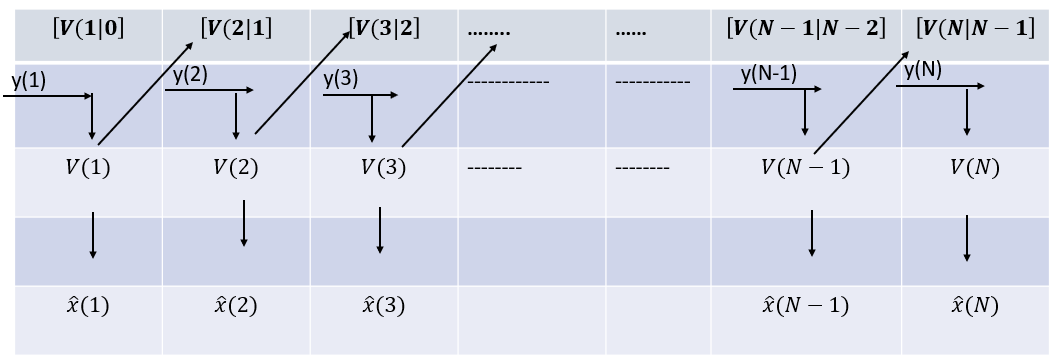

**Figure 1: Optimal Cost in Bellman's Dynamic Programming**

 It is shown that each $V\left(k\right)$ and $V\left(k|k-1\right)$ can be expressed as a quadratic function of the following form

$V\left(k|k-1\right)=\frac{1}{2}{{\left\|x\left(k\right)-\hat{x} \left(k|k-1\right)\right\|}^2 }_{{\left\lbrack P\left(k|k-1\right)\right\rbrack }^{-1} }$   -----------------(23)

$V\left(k\right)=\frac{1}{2}{{\left\|x\left(k\right)-\left(\widehat{x} \left(k\right)\right)\right\|}^2 }_{{P\left(k\right)}^{-1} }$    ------------(24)

Since both are complete squares, it can be shown that 


$$\hat{x} \left(k|k-1\right)=\underset{x\left(k\right)}{\arg \;\min } \;V\left(k|k-1\right)\;=\Phi \hat{x} \left(k-1|k-1\right)+\Gamma u\left(k-1\right)$$
 

$\hat{x} \left(k|k-1\right)=\arg \;\min \;V\left(k|k-1\right)$   ---- (25a)

$P\left(k|k-1\right)=\Phi P\left(k-1|k-1\right)\Phi^T +Q$---------(25b) 

 $\widehat{x} \left(k|k\right)=\underset{x\left(k\right)}{\arg \;\min } \;V\left(k\right)=\hat{x} \left(k|k-1\right)+L\left(k\right)\left(y\left(k\right)-\hat{x} \left(k|k-1\right)\right)$------------(26)

where 

$L\left(k\right)=P\left(k|k-1\right)\;C^T {\left(C\;P\left(k|k-1\right)C^T +R\right)}^{-1}$, -------(27a)

$P\left(k|k\right)=\left(I-L\left(k\right)\;C\right)\;P\left(k|k-1\right)$  ------(27b)

The above equations represent the Kalman filter Equations. The time varying matrix $L\left(k\right)$ is called the gain of the Kalman filter. The last equation is also called as the discrete-time dynamic Riccati Equation (DDRE) which we have used in module 4 on LQOC.

Note that the arrival state variable written as $\hat{\;x} \left(k|k-1\right)$ motivated by the fact that the variable at instant *k *is estimated using measurements up to instant *k*-1, that is, prior to using the measurement update at *k. *For this reason,  $\hat{\;x} \left(k|k-1\right)$ is also referred to as the prior state. Once the measurement $y\left(k\right)$ is integrated in the state estimate, we now call the state estimate as the posterior state estimate (after integrating with $y\left(k\right)$). Here, the posterior is referred to as $\hat{\;x} \left(k|k\right)$. 

To summarize, the Kalman filter is a recursive algorithm that sequentially estimates the state of a dynamic system by combining a system's dynamic model with noisy measurements, providing an optimal estimate at each time step. A schematic representation of sequential state estimation carried out using Kalman filter is shown in Figure 2. 

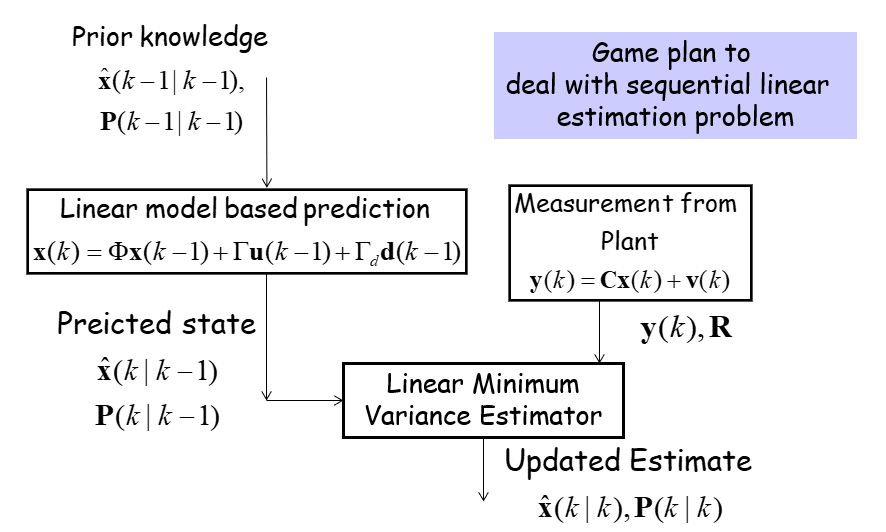

**Figure 2: Summary of Kalman Filter Implementation**

Defining predicted and filtered state estimation errors 

$\epsilon \left(k|k-1\right)=x\left(k\right)-\hat{x} \left(k|k-1\right)\;\;\;\;\textrm{and}\;\;\;\epsilon \left(k|k\right)=x\left(k\right)-\hat{x} \left(k|k\right)$    ------(28)

it can be shown that 

$P\left(k|k-1\right)=E\left\lbrack \varepsilon \left(k|k-1\right){\varepsilon \left(k|k-1\right)}^T \right\rbrack \;\;\;\;\;\;\textrm{and}\;\;\;\;\;P\left(k|k\right)=E\left\lbrack \varepsilon \left(k|k\right){\varepsilon \left(k|k\right)}^T \right\rbrack$  -------(29)

i.e., $P\left(k|k-1\right)$  and   $P\left(k|k\right)$ represent covariance matrices associated with the prediction and filtered estimation errors. Covariance matrix quantifies uncertainty associated with the estimated state. Note that 

$P\left(k|k\right)-P\left(k|k-1\right)=-L\left(k\right)P^{-1} \left(k\right){L\left(k\right)}^T$--------(30)

and $L\left(k\right)P^{-1} \left(k\right){L\left(k\right)}^T$ is  a + ve definite matrix. This implies that $P\left(k\right|k\right)<P\left(k\left|k-1\right)$, i.e the measurement update step reduces covariance associated with the estimate. This is schematically represented in Figure 3 for a 2 state system.

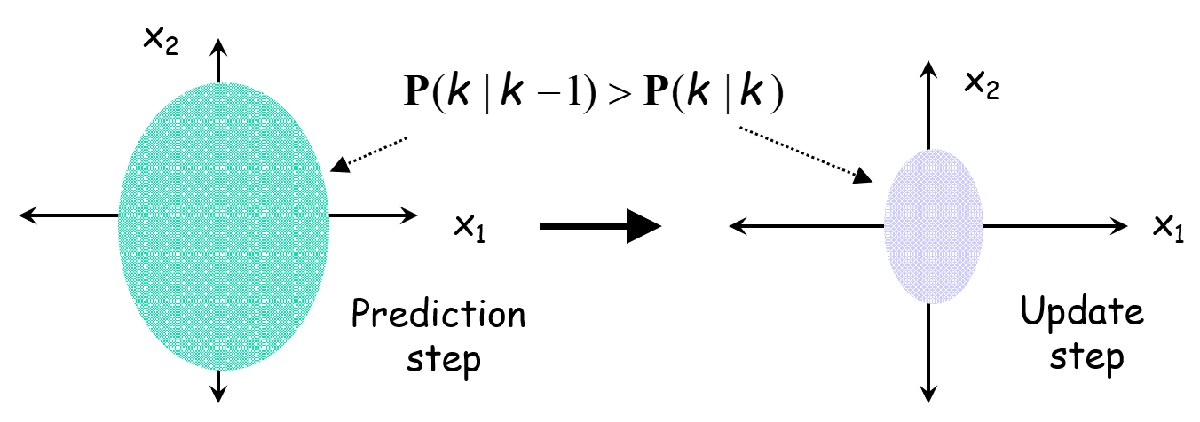

**Figure 3: Covariance Update step: schematic representation**

**Summary of Calculation Steps in Kalman Filter Implementation**

**Initialization step**

**Approach 1:** Use the first N data points for estimation of $\tilde{x} \left(0|N\right)$ and $\tilde{P} \left(0|N\right)$ using the (weighted) least squares method and set$\hat{x} \left(0|0\right)=\tilde{x} \left(0|N\right)$ 

and


$$P\left(0|0\right)=\tilde{P} \left(0|N\right)$$


**Approach 2:** Specify reasonable $\hat{x} \left(0|0\right)$ based on engineering intuition and specify large P(0|0). 

**At the k'th sampling instant**

**Prediction Step: **Update of predicted mean and associated covariance is carried out as follows

$\hat{x} \left(k|k-1\right)=\Phi \hat{x} \left(k-1|k-1\right)+\Gamma u\left(k-1\right)$--------(31)

$P\left(k|k-1\right)=\Phi P\left(k-1|k-1\right)\Phi^T +Q$-------(32)

**Kalman**** Gain Computation: **

$L\left(k\right)=P\left(k|k-1\right){C^T \left\lbrack \textrm{CP}\left(k|k-1\right)C^T +R\right\rbrack }^{-1}$---(33)

**Measurement Update Step:  **Update of filtered mean and associated covariance is carried out as follows

$e\left(k\right)=y\left(k\right)-C\hat{x} \left(k|k-1\right)$-------(34)

$\hat{x} \left(k|k\right)=\hat{x} \left(k|k-1\right)+L\left(k\right)e\left(k\right)$-------------(35)

$P\left(k|k\right)=\left\lbrack I-L\left(k\right)C\right\rbrack P\left(k|k-1\right)$------(36)

For more information about Kalman filters, check [Understanding Kalman Filters — MATLAB Tech Talks](https://www.mathworks.com/videos/series/understanding-kalman-filters.html).

### Kalman Predictor

In many applications, sampling intervals are small and developing a Kalman predictor is advantage for online controller implementation. Consider equation (31) expressed as

$\hat{x} \left(k+1|k\right)=\Phi \hat{x} \left(k|k\right)+\Gamma u\left(k\right)$  --------(37)

Combining equation (35) with (37), we arrive at 

$\hat{x} \left(k+1|k\right)=\Phi \hat{x} \left(k|k-1\right)+\Gamma u\left(k\right)+L_p \left(k\right)e\left(k\right)$  --------(38)

where $L_p \left(k\right)=\Phi L\left(k\right)$. Similarly, the covariance update equation (32) can be expressed as 

$P\left(k+1|k\right)=\Phi P\left(k|k\right)\Phi^T +Q$-------(39)

and combining with equation (36), we arrive at

$P\left(k+1|k\right)=\Phi P\left(k|k-1\right)\Phi^T -L_p \left(k\right)\textrm{CP}\left(k|k-1\right)\Phi^T +Q$  ------(40)

where

$L_p \left(k\right)=\Phi P\left(k|k-1\right){C^T \left\lbrack \textrm{CP}\left(k|k-1\right)C^T +R\right\rbrack }^{-1}$-------(41)

Thus, Kalman predictor consists of equation (38) (Mean Update), equation (40) (Covariance update) together with Kalman gain calculations (equation 41). 

## Kalman Filter for Quadruple Tank Process

clear all
close all

global QTank U_k D_k  % Define global variables for quadruple tank 

**Task 1: **On selecting the operating point, corresponding steady state linear discrete model and parameters will be loaded in the workspace. 

operating_pt=1;  % Specify Operating Point,  Minimum Phase or Nonminimum Phase

% Load quadruple tank parameters and steady state The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

**Task 2:** Select the length of simulation. Create a variable N and set it to a suitable value bet 25  to 150. This number multiplied by the sampling time gives the time in seconds for the simulation. 

N =100;

% Initialization of Simulation Related Parameters 
samp_T = QTank.samp_T ;               %  Sampling time equals 4 sec. 
time = zeros(N, 1) ;        % Array for recording time

% Initial state vector for simulating plant dynamics 
phy= QTank.phy ;  
gam = QTank.gama_u ;
gam_d = QTank.gama_d ; 
C_mat = QTank.C_mat ; 

%  No. of states and inputs    
[n_st,n_ip] = size(gam);
[n_op, nx] = size(C_mat) ;
[nx, n_d] = size(gam_d)  ; 
samp_T = 4 ;                

kT=zeros(1, N);
% Arrays to save deviation variables
xk = zeros(n_st, N) ;
uk=zeros(n_ip, N);
yk = zeros(n_op, N) ;
% Arrays to save original variables
Xk = zeros(n_st, N) ;
Uk=zeros(n_ip, N);
Yk = zeros(n_op, N) ; 

% Process Initial conditions
Xk(:,1) =   QTank.Xs + 2 * [ -2 1 0.5 -0.5]' ;
Uk(:,1) = QTank.Us ;
Yk(:,1) = QTank.C_mat *  Xk(:,1);
yk(:,1) = QTank.C_mat *  xk(:,1);
xk(:,1) =   [ -2 2 1 -1 ]' ;
dk = zeros(1,N) ;
xkhat = zeros(n_st, N) ;
Xkhat = zeros(n_st, N) ; 
xkkhat = zeros(n_st, N) ;
ykhat = zeros(n_op,N) ;
ek = zeros(n_op,N) ;

Xkhat = zeros(n_st,N);
Xkhat(:,1) = QTank.Xs ; 

% Generate Input sequence 
uk1 = idinput(N,'rgs', [0,0.1]);
uk2 = idinput(N,'rbs', [0,0.1]);
uk = [ uk1' ; uk2'] ;

est_err =zeros(n_st,1);
randn('seed',1);

% This initial gain matrix is set here but only used for del_Lck calculations once  
Lc_k_minus_1=[ 0.4456    0.0015;
    0.0015    0.4459;
    0.0719    0.0134;
    0.0118    0.0601];
norm_del_Lck=zeros(1,N);

**Kalman Filter Parameters**

**Task 3:  **Set the state noise variance and measurement noise variance to be used in simulations. Set both the sliders to to 0.075 each. 

d_sigma =0.075;
v_sigma =0.1;
R_mat = v_sigma^2*eye(n_op) ;
Qd_mat = d_sigma^2*eye(n_d) ;

P0_sigma =5;
Pk_k = P0_sigma *eye(4);   % Initial error covariance
Pk_k_minus_1 =phy*Pk_k*phy'+ gam_d'* Qd_mat *gam_d;

vk = mvnrnd(zeros(n_op,1), R_mat, N) ;  % Generate measurement noise
vk = vk';
dk = mvnrnd(zeros(n_d,1), Qd_mat , N) ;  % Generate state noise
dk = dk';

**Task 4: **Set the NO_Noise flag to **Switch OFF Noise** for simulating system under noise free conditions

NO_Noise =  1; % Set this flag for simulating system under noise free conditions 
if (NO_Noise)
    vk = 0 * vk ;  dk = 0 * dk ;  % Set state and measurement noise to zero 
end 

**Task 5: **Select the model type as **Linear **which to be used in the simulation of the process.

Plant_Sim=1 ;

**Process Simulation with Kalman Filter**

Kalman Filter implementation is done using Dynamic Riccati equation. 

**Task 6**: Now Press the **run button** to simulate the process and observe the waveform. What do you observe? are the true and predicted states closely match? 

 
for k = 1 :N-1

    kT(k) = (k-1);

    % Kalman Filter implementation using Dynamic Riccati equation
    if (k>=2)

        Pk_k_minus_1 = phy*Pk_k*phy'+gam_d'* Qd_mat *gam_d;            % P[k|k-1] computation
        % Kalman gain computation
        Lc_k =  Pk_k_minus_1 *C_mat'*inv(C_mat* Pk_k_minus_1 *C_mat'+ R_mat);
        Pk_k = (eye(4)- Lc_k*C_mat)* Pk_k_minus_1;      % P[k|k] computation
        xkhat(:,k) = phy * xkkhat(:,k-1) + gam * uk(:,k-1) ;
        ykhat(:,k) = C_mat * xkhat(:,k) ;
        ek(:,k) = yk(:,k) - ykhat(:,k) ;
        xkkhat(:,k)= xkhat(:,k) + Lc_k * ek(:,k) ;
        Xkhat(:,k)= xkkhat(:,k)+QTank.Xs;
        
        norm_del_Lck(k) = norm(Lc_k_minus_1-Lc_k);
        Lc_k_minus_1=Lc_k;
    end

    Uk(:,k)=QTank.Us+uk(:,k);
    if Plant_Sim==1
        % Process simulation using linear discrete time  stochastic model
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(:,k)  ;
        yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1) ;
    elseif Plant_Sim==2
        U_k = Uk(:,k) ;
        D_k = QTank.Ds+dk(k) ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 samp_T ], Xk(:,k)) ;
        Xk(:,k+1) = Xt( end,: )' ;   
        xk(:,k+1) = Xk(:,k+1) - QTank.Xs;
        Yk(:,k+1) =QTank.C_mat *Xk(:,k+1) + vk(:,k+1)  ;   % Measured output with noise
        yk(:,k+1)= Yk(:,k+1)-QTank.Ys;
    end
end
kT(N) = N-1 ;
xkkhat(:,N)= xkkhat(:,N-1) ;
Xkhat(:,N)= xkkhat(:,N-1)+QTank.Xs;

est_err = xkkhat - xk ;  % State estimation error 

**Display of simulation results **

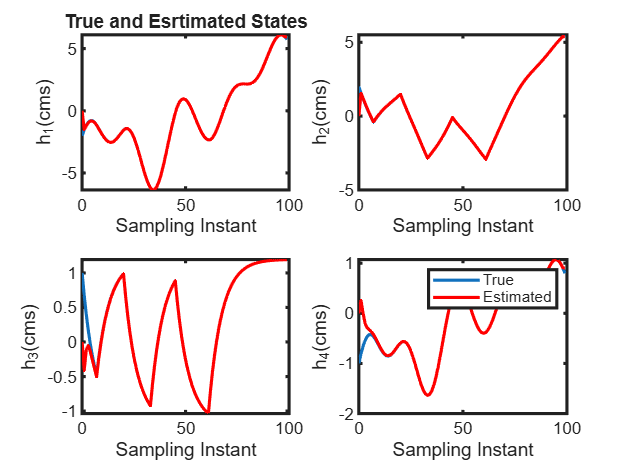

Set_Graphics_Parameters ;

if Plant_Sim==1
    disp('Linear Plant Simulation')
    figure(1), subplot(221), plot(kT, xk(1,:), kT,xkkhat(1,:),'r');
    xlabel('Sampling Instant'), ylabel('h_1(cms)'), title( 'True and Esrtimated States')
    figure(1), subplot(222), plot(kT, xk(2,:), kT,xkkhat(2,:),'r');
    xlabel('Sampling Instant'), ylabel('h_2(cms)'),
    figure(1), subplot(223), plot(kT, xk(3,:), kT,xkkhat(3,:),'r');
    xlabel ('Sampling Instant'), ylabel('h_3(cms)'),
    figure(1), subplot(224), plot(kT, xk(4,:), kT,xkkhat(4,:),'r');
    xlabel('Sampling Instant'), ylabel('h_4(cms)'),
    legend('True','Estimated')
else
      disp('Nonlinear Plant Simulation')
    figure(1), subplot(221), plot(kT, Xk(1,:), kT,Xkhat(1,:),'r');
    xlabel('Sampling Instant'), ylabel('h_1(cms)'),
    figure(1), subplot(222), plot(kT, Xk(2,:), kT,Xkhat(2,:),'r');
    xlabel('Sampling Instant'), ylabel('h_2(cms)'),
    figure(1), subplot(223), plot(kT, Xk(3,:), kT,Xkhat(3,:),'r');
    xlabel('Sampling Instant'), ylabel('h_3(cms)'),
    figure(1), subplot(224), plot(kT, Xk(4,:), kT,Xkhat(4,:),'r');
    xlabel('Sampling Instant'), ylabel('h_4(cms)'),
    legend('True','Estimated')
end

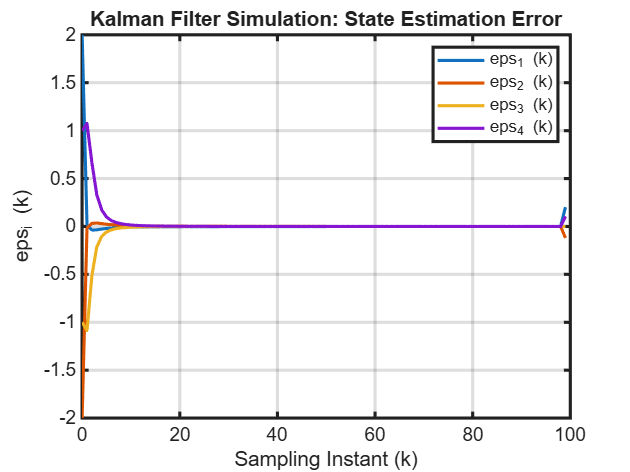

figure(2), plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('eps_i (k)')
legend('eps_1 (k)', 'eps_2 (k)', 'eps_3 (k)', 'eps_4 (k)'), 
title('Kalman Filter Simulation: State Estimation Error')

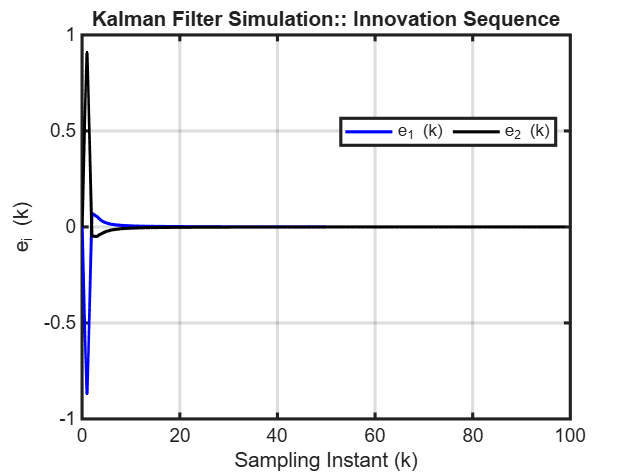

figure(3), plot(kT, ek(1,:), 'b', kT, ek(2,:), 'k'), grid
xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
legend('e_1 (k)', 'e_2 (k)', 'Orientation','horizontal','Location','Best') 
title('Kalman Filter Simulation:: Innovation Sequence')

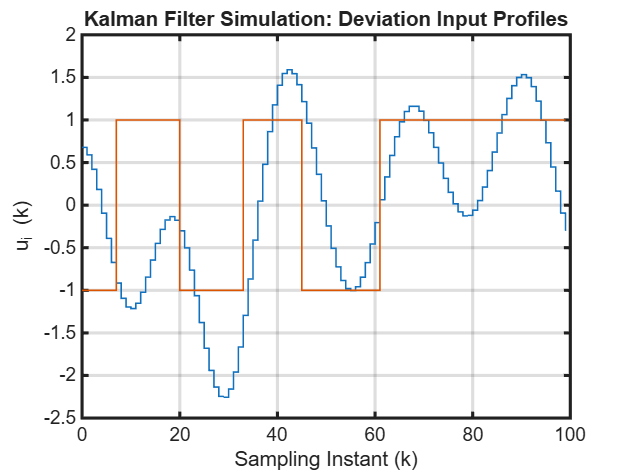

figure(4), stairs(kT, uk', 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), 
title('Kalman Filter Simulation: Deviation Input Profiles')

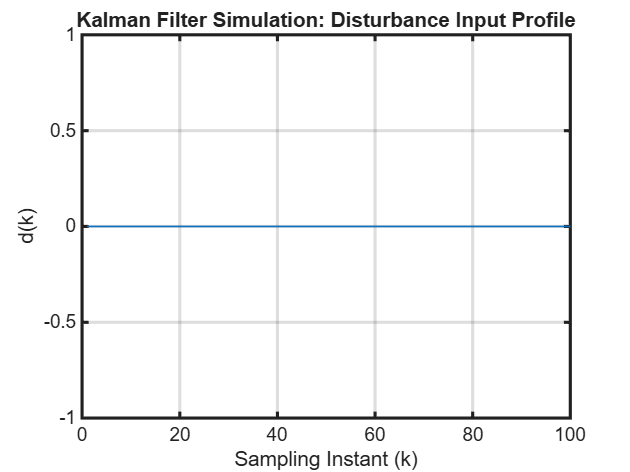

figure(5), stairs(dk, 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)'), title('Kalman Filter Simulation: Disturbance Input Profile')

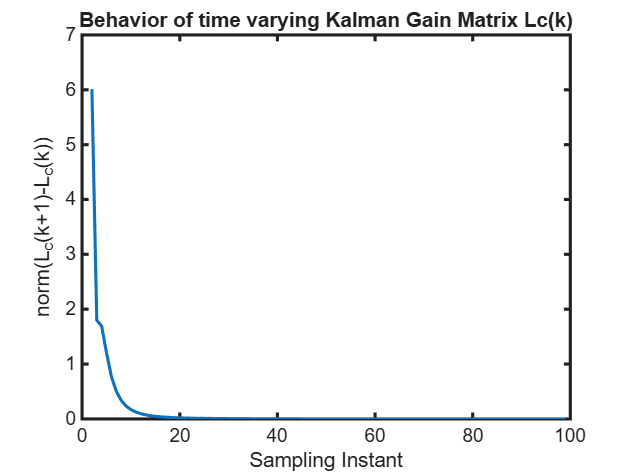

figure(6), plot(kT(3:end),norm_del_Lck(3:end))
    xlabel('Sampling Instant'), ylabel('norm(L_c(k+1)-L_c(k))'), title('Behavior of time varying Kalman Gain Matrix Lc(k)')

**Task 7: **Now check the estimation error by typing est_err  in the command window. Is the value very small? You can see that the model states converge to plant state? 

**Task 8:** Now go back to Task 3 and change the slider position initial state standard deviation parameter. What can you conclude about the rate of convergence of the observer gain matrix from increase or decrease in the standard deviations? 

**Task 9: **Switch between linear and nonlinear plant simulations in Task 5. What can you conclude about the estimation error when you switch between linear and nonlinear plant simulation? 

**Task 10: **Now change the operating point in Task 1 and run the process simulation and observe the simulation results 

From the last figure, we can also observe that the Kalman gain matrix becomes almost constant after few initial samples. 

## Conclusion

Given statistical properties of the unmeasured disturbances and the measurement noise, Kalman filtering approach gives a systematic approach to arrive at a **optimal recursive estimator** suitable for online implementation. The Kalman filter generates the minimum variance estimate of the current state when the unmeasured disturbances can be modeled as a zero mean Gaussian white noise process. From simulation exercise, we observe that the Kalman gain matrix becomes almost constant after few initial samples. This motivates [Stationary Kalman filter](matlab:open('./L04_Stationary_Kalman_Filter.mlx')) discussed in the next lesson. 

## References

Astrom, K. J. and B. Wittenmark, Computer Controlled Systems, Prentice Hall, 1990.

Franklin, G. F. and J. D. Powell, Digital Control of Dynamic Systems, Addison-Wesley, 1989.

Goodwin, G., Graebe, S. F., Salgado, M. E., Control System Design, PHI Learning, 2009.

Fadali, M. S. And Visioli, A., Digital Control Engineering: Analysis and Design, Academic Press, 2019. 

Rawlings, J.B., Mayne, D.Q., Diehl, M.M., "Model Predictive Control: Theory, Computation and  Design", 2nd Ed. Nob-Hill Publishing, Wisconsin-Madison, 2017, [https://sites.engineering.ucsb.edu/~jbraw/mpc/MPC-book-2nd-edition-1st-printing.pdf](https://sites.engineering.ucsb.edu/~jbraw/mpc/MPC-book-2nd-edition-1st-printing.pdf) 

H. W. Sorenson University of California, San Diego, "Least-squares estimation: from Gauss to Kalman"     [https://www.professordavisantos.com/wp-content/uploads/2019/02/ArtigoSorensonLS_KF.pdf](https://www.professordavisantos.com/wp-content/uploads/2019/02/ArtigoSorensonLS_KF.pdf)

## Appendix: Derivation of Kalman Filter using Forward Dynamic Programming 

 The detailed derivation for Kalman filter presented in this section is based on expressing the sum of two squares as a square via completion of squares. 

**Completion of Squares**

Consider sum of two quadratics:

 $V={{\left\|x-a\right\|}^2 }_A +{{\left\|C\;x-b\right\|}^2 }_B =V_1 \left(x\right)+V_2 \left(x\right)$   ---------(A1)

The sum can be written as

$V={{\left\|x-\zeta \right\|}^2 }_{{\tilde{H} }^{-1} } +\eta$ ---------------(A2)

where

$\tilde{H} {=A}^{-1} -A^{-1} {C^T \left(CA^{-1} C^T +B^{-1} \right)}^{-1} CA^{-1}$   -----------(A3)

$\zeta =a+A^{-1} C^T {\left(CA^{-1} C^T +B^{-1} \right)}^{-1} \left(b-C\;a\right)$ -------(A4) 

**Detailed Derivation**

The  sketch of the derivation gives an overview of the steps. The detailed steps for the derivation are shown here. We begin by looking at the Stage 1 costs where the initial cost $V\left(0\right)$ is

 $V\left(0\right)=\;$$\frac{1}{2}{{\left\|x\left(0\right)-\hat{\;x} \left(0\right)\right\|}^2 }_{{\left\lbrack P\left(0\right)\right\rbrack }^{-1} }$---------(A5)

**Stage 1 Arrival Cost**

The arrival cost at stage 1 can be written as  

$V\left(1|0\right)=V\left(x\left(0\right)\right)+\frac{1}{2}{\left\|x\left(1\right)-\Phi \hat{x} \left(0\right)-\Gamma u\left(0\right)\right\|}_{Q^{-1} }^2$    --------(A6)

Substituting for $V\left(x\left(0\right)\right)=\;$$\frac{1}{2}{{\left\|x\left(0\right)-\hat{\;x} \left(0\right)\right\|}^2 }_{{\left\lbrack P\left(0\right)\right\rbrack }^{-1} }$ we can write

$V\left(1|0\right)=\frac{1}{2}{{\left\|x\left(0\right)-\hat{x} \left(0\right)\right\|}^2 }_{{P\left(0\right)}^{-1} } +\frac{1}{2}{\left\|x\left(1\right)-\Phi \hat{x} \left(0\right)-\Gamma u\left(0\right)\right\|}_{Q^{-1} }^2$------(A7)

Using the side result in A2, we can write the above as a quadratic function

$V\left(1|0\right)={{\left\|x\left(0\right)-\zeta \right\|}^2 }_{{\tilde{H} }^{-1} } +\eta$---------------------(A8)

$\tilde{H} =P\left(0\right)+P\left(0\right)\Phi^T {\left\lbrack \Phi P\left(0\right)\Phi^T +Q\right\rbrack \;}^{-1} \Phi P\left(0\right)$ ----------------(A9)

and

$\zeta =\hat{x} \left(0\right)-P\left(0\right)\Phi^T {\left\lbrack \Phi P\left(0\right)\Phi^T +Q\right\rbrack }^{-1} \left(-x\left(1\right)+\Phi \hat{\;x} \left(0\right)+\Gamma u\left(0\right)\right)$-------(A10)

$\eta =\frac{1}{2}{{\left\|\zeta -\hat{x} \left(0\right)\right\|}^2 }_{{P\left(0\right)}^{-1} } +\frac{1}{2}{{\left\|x\left(1\right)-\Phi \zeta -\Gamma u\left(0\right)\right\|}^2 }_{Q^{-1} }$------------(A11)

Define 

$P\left(1|0\right)=\Phi P\left(0\right)\Phi^T +Q$          ------- (A12)

            $\hat{x} \left(1|0\right)=\Phi \hat{\;x} \left(0\right)+\Gamma u\left(0\right)\;$        ------- (A13)

Then we can re-write Eq. (A9) and (A10) as 

$\tilde{H} =P\left(0\right)+P\left(0\right)\Phi^T {\left\lbrack P\left(1|0\right)\right\rbrack \;}^{-1} \Phi P\left(0\right)$ --------(A14)

$\zeta =\hat{x} \left(0\right)+P\left(0\right)\Phi^T {\left\lbrack P\left(1|0\right)\right\rbrack }^{-1} \left(x\left(1\right)-\hat{x} \left(1|0\right)\right)$  -------(A15)     

**Optimal Arrival Cost**

Eq. (A8) is written as a perfect square of the decision variable $x\left(0\right)$. Thus, the minimizer of $V\left(1|0\right)$ w.r.t. $x\left(0\right)$ is $\zeta$. Then the optimal arrival cost can be easily identified from Eq. (A8) as,

${\left\lbrack V\left(k|k-1\right)\right\rbrack }^* =\underset{x\left(k\right)}{\arg \;\min } \;V\left(k|k-1\right)=\eta$-------(A16)

where $\eta$ is given in Eq. (A11). Substituting $\zeta$ in Eq. (A16) yields, 

${\left\lbrack V\left(k|k-1\right)\right\rbrack }^* =\eta =\frac{1}{2}{{\left\|P\left(0\right){\Phi^T \left(P\left(1|0\right)\right)}^{-1} \left(x\left(1\right)-\hat{x} \left(1|0\right)\right)\right\|}_{{P\left(0\right)}^{-1} }^2 } +\frac{1}{2}{{\left\|x\left(1\right)-\Phi \hat{x} \left(0\right)-\Phi P\left(0\right)\Phi^T {\left\lbrack P\left(1|0\right)\right\rbrack }^{-1} \left(x\left(1\right)-\hat{x} \left(1\right)\right)-\Gamma u\left(0\right)\right\|}_{Q^{-1} }^2 }$------(A17)

which can be solved simplified by splitting the two terms as Term A and Term B 

**Term A**


$$\frac{1}{2}{{\left\|P\left(0\right){\Phi^T \left(P\left(1|0\right)\right)}^{-1} \left(x\left(1\right)-\hat{x} \left(1|0\right)\right)\right\|}_{{P\left(0\right)}^{-1} }^2 } ={\frac{1}{2}\left(x\left(1\right)-\hat{x} \left(1|0\right)\right)}^T {\left(P\left(1|0\right)\right)}^{-1} \Phi {P\left(0\right)P\left(0\right)}^{-1} P\left(0\right){\Phi^T \left(P\left(1|0\right)\right)}^{-1} \left(x\left(1\right)-\hat{x} \left(1|0\right)\right)$$


$\textrm{TermA}=\frac{1}{2}{{\left\|{\Phi^T \left(P\left(1|0\right)\right)}^{-1} \left(x\left(1\right)-\hat{x} \left(1|0\right)\right)\right\|}_{{P\left(0\right)}^{-1} }^2 }$------------(A18)

**Term B**

**Substitute **$\Phi P\left(0\right)\Phi^T =\left\lbrack P\left(1|0\right)\right\rbrack -Q$ in the second term of Eq. (A17) and simplify

$\frac{1}{2}{{\left\|\left\lbrace I-\Phi P\left(0\right)\Phi^T {P\left(1|0\right)}^{-1} \right\rbrace \left(x\left(1\right)-\hat{x} \left(1|0\right)\right)\right\|}_{Q^{-1} }^2 } =\frac{1}{2}{{\left\|\left\lbrace Q{\left\lbrack P\left(1|0\right)\right\rbrack }^{-1} \right\rbrace \left(x\left(1\right)-\hat{x} \left(1|0\right)\right)\right\|}_{Q^{-1} }^2 } =\frac{1}{2}{{\left\|{\left\lbrack P\left(1|0\right)\right\rbrack }^{-1} \left(x\left(1\right)-\hat{x} \left(1|0\right)\right)\right\|}_{Q^{-1} }^2 }$--------------(A19)

Combining Term A and Term B in equation (A18) and (A19) yields the optimal arrival cost as,

$\left\lbrack V\left(1|0\right)\right\rbrack =\frac{1}{2}{\left\|\Phi^T {P\left(1|0\right)}^{-1} \left(x\left(1\right)-\hat{x} \left(1|0\right)\right)\right\|}_{{P\left(0\right)}^{-1} }^2 +\frac{1}{2}{\left\|{\left\lbrack P\left(1|0\right)\right\rbrack }^{-1} \left(x\left(1\right)-\hat{x} \left(1|0\right)\right)\right\|}_{Q^{-1} }^2$---------(A20)

The above two terms when written as quadratics can be factorized noting the common factor $\left(x\left(1\right)-\hat{x} \left(1|0\right)\right)$. Further simplification, gives the optimal stage 1 arrival cost as a simple quadratic function,

${\left\lbrack V\left(1|0\right)\right\rbrack }^* =\frac{1}{2}{\left\|\left(x\left(1\right)-\hat{x} \left(1|0\right)\right)\right\|}_{{\left\lbrack P\left(1|0\right)\right\rbrack }^{-1} }^2$---------(A21)

**Stage 1 Cost after Measurement**

$\left\lbrack V\left(1\right)\right\rbrack =\;{\left\lbrack V\left(1|0\right)\right\rbrack }^* +\frac{1}{2}{{\left\|y\left(1\right)-\textrm{Cx}\left(1\right)\right\|}^2 }_{R^{-1} }$------(A22)

Use the side result, to write sum of two quadratics in equation (A20) and (A21), we get a single quadratic as follows,

$V\left(1\right)={{\left\|x\left(1\right)-\zeta \right\|}^2 }_{{\tilde{H} }^{-1} } +\eta$------------(A23)

 
$${\left\lbrack V\left(1\right)\right\rbrack }^* =\underset{x\left(1\right)}{\arg \;\min } \;\;\;\;{\left\lbrack V\left(1|0\right)\right\rbrack }^* +\frac{1}{2}{{\left\|y\left(1\right)-C\;x\left(1\right)\right\|}^2 }_{R^{-1} }$$


${\left\lbrack V\left(1\right)\right\rbrack }^* =\underset{x\left(1\right)}{\arg \;\min } \left\lbrack \frac{1}{2}{\left\|\left(x\left(1\right)-\hat{x} \left(1|0\right)\right)\right\|}_{{\left\lbrack P\left(1|0\right)\right\rbrack }^{-1} }^2 +\frac{1}{2}{{\left\|y\left(1\right)-C\;x\left(1\right)\right\|}^2 }_{R^{-1} } \right\rbrack$-------(A24)

 Minimization of $V\left(1\right)$ with respect to $x\left(1\right)\;$yields the optimal state estimate $\hat{x} \left(1|1\right)=\underset{x\left(1\right)}{\arg \;\min } \;V\left(1\right)$.

$\hat{x} \left(1|1\right)=$$\zeta =\hat{x} \left(1|0\right)+{P\left(1|0\right)}^{-1} C^T {\left(\textrm{CP}\left(1|0\right)C^T +R\right)}^{-1} \left(y\left(1\right)-C\hat{x} \left(1|0\right)\right)$ ---------------(A25)


$$P\left(1\right)=\tilde{H} =\textrm{CP}\left(1|0\right)-P\left(1|0\right)C^T {\left(\textrm{CP}\left(1|0\right)C^T +R\right)}^{-1} \textrm{CP}\left(1|0\right)$$


Defining the Kalman gain as follows,

$L\left(1\right)=P\left(1|0\right)C^T {\left(\textrm{CP}\left(1|0\right)C^T +R\right)}^{-1}$   ---------------- (A26)

$\hat{\;x} \left(1|1\right),P\left(1\right)$ in Eq. (A25, A26) can be rewritten as 


$$\hat{\;x} \left(1\right)=\hat{x} \left(1|0\right)+L\left(1\right)\left(y\left(1\right)-C\hat{x} \left(1|0\right)\right)$$



$$P\left(1\right)=\tilde{\;H} =P\left(1|0\right)-L\left(1\right)\textrm{CP}\left(1|0\right)$$


Note that here $\eta$ in Eq. (A23) does not depend on $x\left(1\right)$and can be ignored. Eq. (A24) is re-expressed as

${\left\lbrack V\left(1\right)\right\rbrack }^* ={{\left\|x\left(1\right)-\zeta \right\|}^2 }_{{\tilde{H} }^{-1} } =\frac{1}{2}{{\left\|x\left(1\right)-\hat{x} \left(1\right)\right\|}^2 }_{{P\left(1\right)}^{-1} }$---------------(A27)

Note the similarity between the expressions for ${\left\lbrack V\left(1\right)\right\rbrack }^*$ and $V\left(0\right)$ in Eq. (A5)

The minimizer of equation (A27) provides the estimate for  state $x\left(1\right)$as follows,

 $\hat{x} \left(1\right)=\arg \;\min \;\left\lbrack V\left(1\right)\right\rbrack =\hat{x} \left(1|0\right)+L\left(1\right)\left(y\left(1\right)-C\hat{x} \left(1|0\right)\right)$ ---------(A28)

**Optimal Arrival Cost for Stage k**

From the above discussion, we can write Optimal Arrival Cost for Stage **k** as 

$V\left(k|k-1\right)=\frac{1}{2}{\left\|\left(x\left(k\right)-\hat{x} \left(k|k-1\right)\right)\right\|}_{{\left\lbrack P\left(k|k-1\right)\right\rbrack }^{-1} }^2$-------------------(A29)


$$\begin{array}{l}
\hat{x} \left(k|k-1\right)=\Phi \hat{x} \left(k-1\right)+\Gamma u\left(k-1\right)\\
P\left(k|k-1\right)=\Phi P\left(k-1\right)\Phi^T +Q
\end{array}$$


**Stage k Cost after Measurement**

$\begin{array}{l}
V\left(k\right)=V\left(k|k-1\right)+\frac{1}{2}{{\left\|y\left(k\right)-\textrm{Cx}\left(k\right)\right\|}^2 }_{R^{-1} } \\
=\frac{1}{2}{{\left\|x\left(k\right)-\hat{x} \left(k\right)\right\|}^2 }_{{P\left(k\right)}^{-1} } 
\end{array}$------------(A30)

State update

$\hat{x} \left(k\right)=\hat{x} \left(k|k-1\right)+L\left(k\right)\left(y\left(k\right)-C\hat{x} \left(k|k-1\right)\right)$---------(A31)

Kalman Gain

$L\left(k\right)=P\left(k|k-1\right)C^T {\left(\textrm{CP}\left(k|k-1\right)C^T +R\right)}^{-1}$-----------(A32)

Covariance Update

$P\left(k\right)=P\left(k|k-1\right)-L\left(k\right)\textrm{CP}\left(k|k-1\right)$--------(A33)

The process terminates at final measurement $y\left(N\right)$ that yields $V\left(1\right),\cdots ,V\left(N\right),\hat{\;x} \left(1\right),\cdots ,\hat{\;x} \left(N\right)$ $P\left(1|0\right)\cdots P\left(N|N-1\right)$, $\;P\left(1\right),\cdots ,\;P\left(N\right)$ and $\;L\left(1\right),\cdots ,L\left(N\right)$